- poles/zeros diagram

- filter transfer function


% Define the low and high cutoff frequencies for the bandpass filter (in Hz)
lowCutoff = cutoffFrequencies(1)/fn % Lower cutoff frequency

lowCutoff = 0.2000

highCutoff = cutoffFrequencies(2)/fn % Upper cutoff frequency

highCutoff = 0.8000

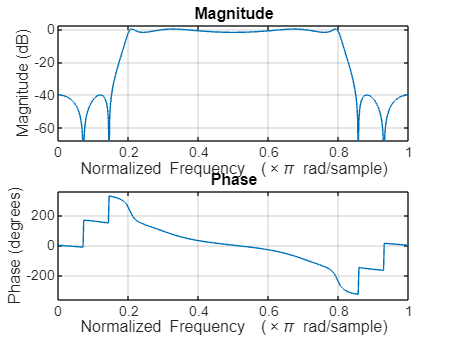

Rp=2;
gpass= 2;
gstop= 40;

if method=="butterworth"
    if type== 'lp'
        [b, a] = butter(order, lowCutoff, 'low');
    elseif type=='hp'
        [b, a] = butter(order, highCutoff, 'high');
    elseif type=='bp'
        [b, a] = butter(order, [lowCutoff, highCutoff], 'bandpass');
    elseif type=='bs'
        [b, a] = butter(order, [lowCutoff, highCutoff], 'stop');
    end
end

if method== "chebychevI"
    if type== 'lp'
        [b, a] = cheby1(order, Rp, lowCutoff,  'low');
    elseif type=='hp'
        [b, a] = cheby1(order, Rp, highCutoff, 'high');
    elseif type=='bp'
        [b, a] = cheby1(order, Rp, [lowCutoff, highCutoff], 'bandpass');
    elseif type=='bs'
        [b, a] = cheby1(order, Rp, [lowCutoff, highCutoff], 'stop');
    end
end

if method=="chebychevII"
    if type== 'lp'
        [b, a] = cheby2(order, Rp, lowCutoff, 'low');
    elseif type=='hp'
        [b, a] = cheby2(order, Rp, highCutoff, 'high');
    elseif type=='bp'
        [b, a] = cheby2(order, Rp, [lowCutoff, highCutoff], 'bandpass');
    elseif type=='bs'
        [b, a] = cheby2(order, Rp, [lowCutoff, highCutoff], 'stop');
    end
end

if method=="cauer"
    if type== 'lp'
        [b, a] = ellip(order,gpass, gstop, lowCutoff, 'low');
    elseif type=='hp'
        [b, a] = ellip(order, lowCutoff, 'high');
    elseif type=='bp'
        [b, a] = ellip(order, gpass, gstop, [lowCutoff, highCutoff], 'bandpass');
    elseif type=='bs'
        [b, a] = ellip(order, gpass, gstop, [lowCutoff, highCutoff], 'stop');
    end
end

figure()
freqz(b, a);


filtered_signal = filter(b,a,y)

filtered_signal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


previous:

% Ensure that time vectors match the length of the filtered signals
t = linspace(0, length(filtered_signal)/fs, length(filtered_signal));

clear ylim

if input ~= "wav"
name = type_signal;
else
name = "wav file";
end

width = 15;
height = 10;

%t = linspace(0, length(y) / fs, length(y));

% Define filter response with reduced points for testing
[H, w] = freqz(b, a); % Reduced to 128 points for speed


Plot original signal:

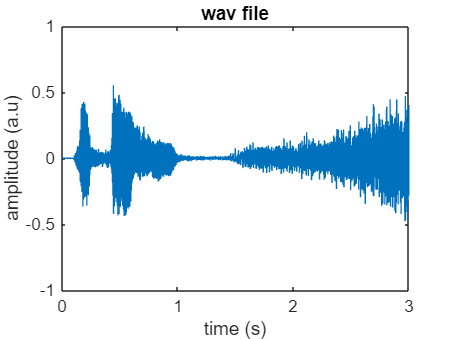

% plot of the original signal
figure(1);
plot(t, y);
title(name)
xlabel('time (s)');
ylabel('amplitude (a.u)')
xlim([0 xlimTime]) 
ylim([-ylimAmplitude ylimAmplitude]) 

folder_name= '';
filename = fullfile(folder_name, 'original_signal.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');

Plot filtered signal:

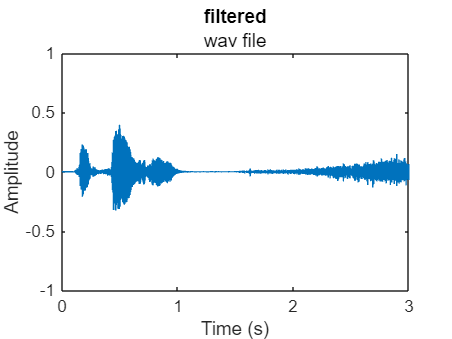

% Plot the filtered time signal with specified time and amplitude limits
figure(2);
plot(t, filtered_signal);
title("filtered", name);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 xlimTime]) 
ylim([-ylimAmplitude ylimAmplitude]) 

filename = fullfile(folder_name, 'filtered_signal.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');

Frequency response (magnitude and phase): 

% Frequency Response (Magnitude and Phase) with specified magnitude limits
figure(3)
freqz(b,a)
% figure(3);
% subplot(2, 1, 1);
% plot(w, 20*log10(abs(H))); % Magnitude in dB
% title('Magnitude Response', name);
% xlabel('Frequency (Hz)');
% ylabel('Magnitude (dB)');
% xlim([0, xlimFreq])  ;
% ylim=([-ylimFreq, ylimFreq]);
% 
% subplot(2, 1, 2);
% plot(w, angle(H)); % Phase in radians
% title('Phase Response', name);
% xlabel('Frequency (Hz)');
% ylabel('Phase (radians)');
% xlim([0, xlimFreq])  ;

filename = fullfile(folder_name, 'magnitude_phase.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');

Plot real and imaginary parts of frequency response:

% Plot Real and Imaginary Parts of the Frequency Response
figure(4);
subplot(2, 1, 1);

plot(w, real(H)); % Real part of H
title('Real Part of Frequency Response', name);
xlabel('Frequency (Hz)');
ylabel('Real Part');

subplot(2, 1, 2);
plot(w, imag(H)); % Imaginary part of H
title('Imaginary Part of Frequency Response', name);
xlabel('Frequency (Hz)');
ylabel('Imaginary Part');

filename = fullfile(folder_name, 'real_imag.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');

Plot pole zero diagram:

% Plot the Pole-Zero Diagram
figure(5);
zplane(b, a);
title('Pole-Zero Diagram', name);

filename = fullfile(folder_name, 'pole_zero.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');

Plot impulse response:

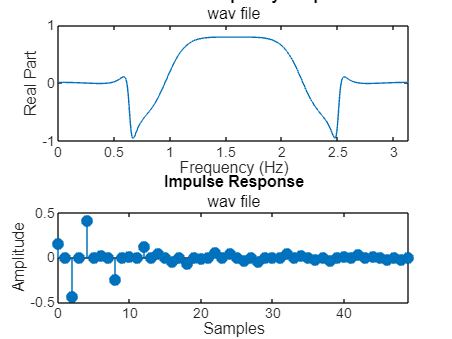

% Impulse Response of the Filter with reduced samples
figure(6);
impz(b, a, 50); % Only plot the first 50 samples
title('Impulse Response', name);
xlabel('Samples');
ylabel('Amplitude');

filename = fullfile(folder_name, 'impulse_response.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf','-r300');